# **INSTITUTO POLITÉCNICO NACIONAL**

# **UNIDAD PROFESIONAL INTERDISCIPLINARIA DE INGENIERÍA EN TECNOLOGÍAS AVANZADAS**

# Práctica 1: Señales en tiempo continuo

## Materia:Análisis de Señales y Sistemas

## Profesor: Rafael Martínez Martínez

## Integrantes:

## Huerta Sánchez Jesus Alejandro.

## Navarro Herrera Leon Ricardo.

## Rubio Guerrero Edgar Miguel.

## GRUPO: 2MV1

## Fecha de entrega:14/02/2019

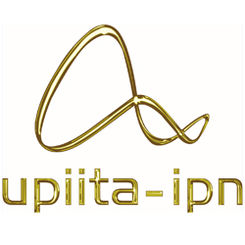                                                  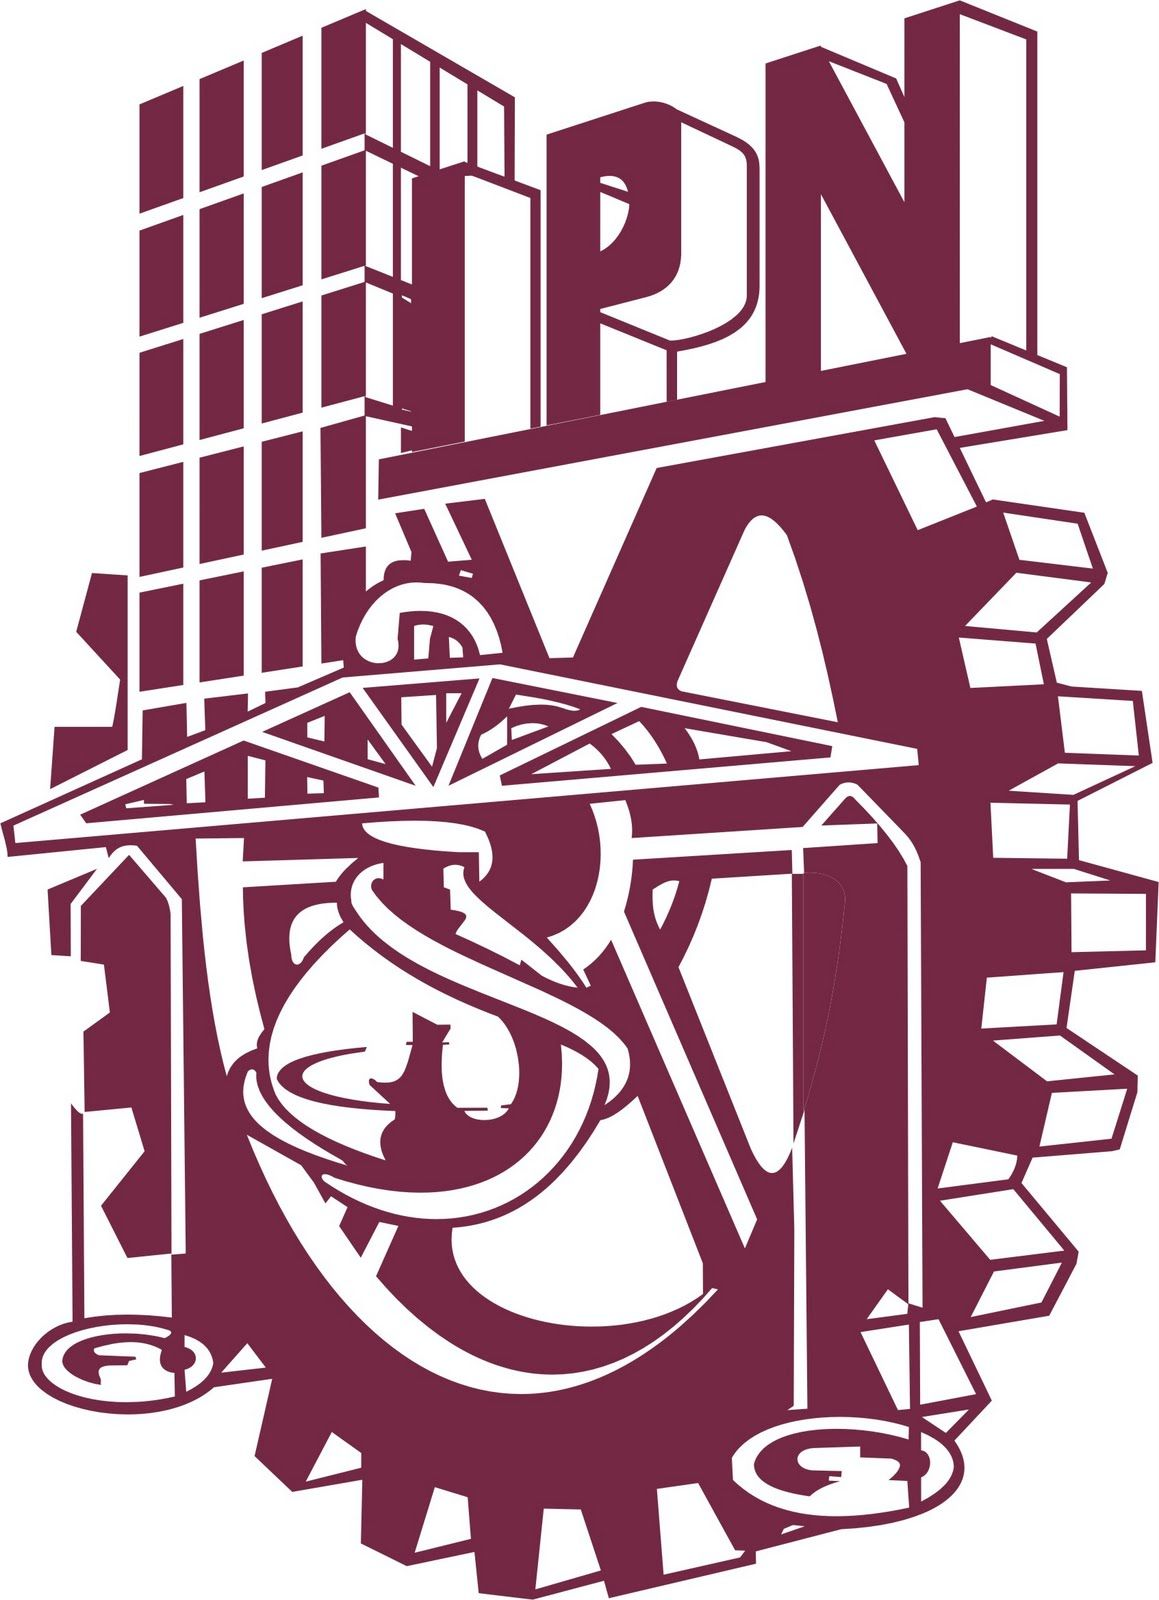

## Objetivos

- Manipulación básica de MATLAB.

- Gráficas de señales reales y complejas continuas.

- Transformación de señales continuas (escalamientos y traslaciones).

- Calculo de energía y potencia de señales continuas.

## Introducción

MATLAB (Matrix Laboratory, “laboratorios de matrices”). Es una herramienta computacional, también denominado sistema de cómputo numérico. Este software matemático cuenta con un entorno de desarrollo integrado (IDE) además de tener su sintaxis y redacción propia (Lenguaje M)

Se crea en 1984, por Cleve Moler matemático estadounidense y programador de ordenador que se especializa en análisis numérico, el principal objetivo era la idea de usar paquetes de subrutinas escritas en Fortran para facilitar el cálculo y comprensión de los cursos de Análisis Numérico y Algebra Lineal, sin tener una necesidad de programas que usaran este lenguaje. El lenguaje de programación M se creó en 1970 proporcionando un acceso sencillo al Software de matrices LINPACK y EISPACK sin tener que hacer uso del lenguaje Fortran.

Como se menciono anteriormente Matlab ve todo como una matriz. El lenguaje m es interpretado, y puede ejecutarse tanto en el entorno interactivo, como a través de un archivo de script (archivos *.m). Este lenguaje permite operaciones de vectores y matrices, funciones, cálculo lambda, y programación orientada a objetos.

En el año 2005 MATLAB contaba con aproximadamente más de un millón de usuarios tanto académicos, investigadores, maestros, empresarios debido a que otorga diversos beneficios en cuanto a investigaciones, análisis matemático y lenguaje simbólico

En cuanto a alternativas de código abierto a Matlab tenemos.

GNU Octave es la alternativa a MATLAB más popular. Se desarrollo durante casi tres décadas, Octave al igual que MATLAB se ejecuta en todas las plataformas. Es muy parecido al lenguaje MATLAB real, Octave puede ser una buena opción para usted; se esfuerza por una compatibilidad exacta, por lo que muchos de sus proyectos desarrollados para MATLAB pueden ejecutarse en Octave sin necesidad de modificaciones. En el siguiente enlace puedes descargar el software [GNU Octave](https://www.gnu.org/software/octave/) y explorando un poco ahí mismo podrás encontrar guías para aprender a usarlo.

SageMath es otra herramienta computacional alternativa de codigo abierto a MATLAB. Buena opción para aquellos que buscan una alternativa de MATLAB. Está construido sobre una variedad de conocidas bibliotecas de computación científica basadas en Python, y su propio lenguaje es sintácticamente similar a Python. Tiene muchas características que incluyen una interfaz de línea de comandos, cuadernos basados en navegador, herramientas para incrustar fórmulas en otros documentos y, por supuesto, muchas bibliotecas matemáticas. [SageMath](https://www.sagemath.org/) el enlace anterior dirige a la página oficial de SageMath, donde encontrarás documentación y podrás descargarlo gratis.

Python es otra alternativa indirecta a MATLAB ya que es un lenguaje de programación interpretado su objetivo es ser fácil de entender. Se trata de un lenguaje de programación multiparadigma, Es un lenguaje interpretado, dinámico y multiplataforma al igual que MATLAB. Como otra alternativa consulta la página oficial de [Python](https://www.python.org/), para conocer más y ver las versiones y algunas de las ayudas disponibles.

Python cuenta con diversos módulos matemáticos que simplifican aún mas el trabajo como lo es numpy, math entre otros.

Existen diversas fuentes de información para poder utilizar las herramientas anteriormente mencionadas una de ellas es las respectivas paginas oficiales de cada sitio oficial como lo es el de Matlab. Sitios de cursos como lo son udemy, edx, coursera entre otros. Hay un documento de la Universidad de las Américas de Puebla que se mencionara en las referencias  donde se encuentra bastante desarrollados los temas.

Bibliografía

Enciclopedia cubana. (10 de 02 de 2018). Ecured. Recuperado el 14 de 02 de 2020, de [EcuRed](https://www.ecured.cu/MATLAB)

Python (s.f) . General Python FAQ. Recuperado el 14 de 02 de 2020,de [WikiPython](https://es.wikipedia.org/wiki/Python)

Garcia,S (08 de 11 del 2003). [Universidad de las Américas de Puebla. Tutorial de Matlab. ](http://catarina.udlap.mx/u_dl_a/tales/documentos/lep/garcia_b_s/)Recuperado el 14 de 02 de 2020.

## Problema 1

### M1.1 Funciones anónimas

Podemos generar una función anónima sin generar un script nuevo con la sintaxis:

f= @(t) exp(-t).*cos(2*pi*t)

f = function_handle with value:
    @(t)exp(-t).*cos(2*pi*t)


Lo que generaría la función $f\left(t\right)=e^{-t} \cos \left(2\pi t\right)$ y nos permitiría usar dicha expresión sólo llamando a f(t).

Por ejemplo si inicializamos t en 0 y evaluamos la expresión f(t) obtenemos lo siguiente:

t=0;
f(t)

ans = 1

Y comprobamos que esta bien al evaluar f(t) directamente en 0 y observar que tenemos:

f(0)

ans = 1

Al evaluar ahora un vector en la función tenemos:

t= (-2:2);
f(t)

ans =     7.3891    2.7183    1.0000    0.3679    0.1353


Y podemos graficar la función usando el vector que generamos, esperando que saliera un seno amortiguado, como sigue:

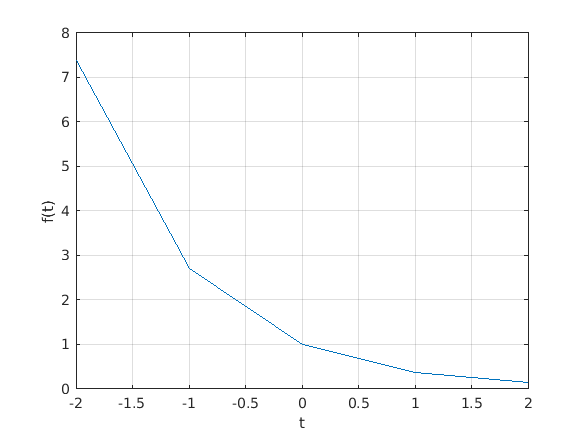

plot (t,f(t));
xlabel ('t');ylabel ('f(t)');grid;

Pero no genera un seno, se genera una gráfica muy distinta a lo esperado debido a que no se rtoman suficientes puntos, por lo que s hacemos que el vector considere más puntos tenemos:

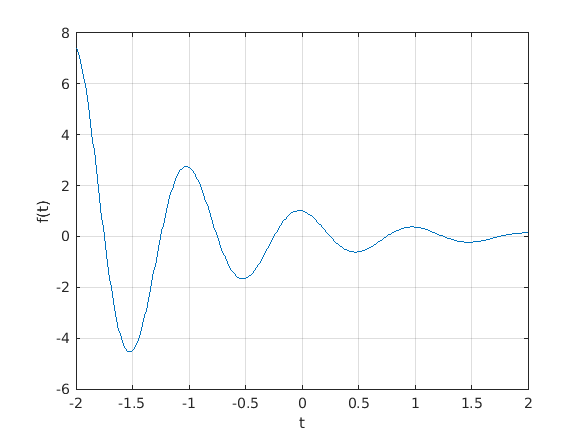

t= (-2:0.01:2);
plot (t, f(t));
xlabel ('t');ylabel ('f(t)');grid;

Ser puede ver que entonces al considerar más puntos para evaluar, la gráfica generada si es una representación correcta de la función f(t).

### M1.2 Operadores relacionales y la función escalón unitario

Para definir a la función escalón unitario en MatLab, podemos hacer uso de los operadores relacionales, y quedaría definida por ejemplo por:

u= @(t) t>=0

u = function_handle with value:
    @(t)t>=0


Las funciones con discontinuidades como u(t) pueden ser complicadas de graficar, por ejemplo si hacemos: 

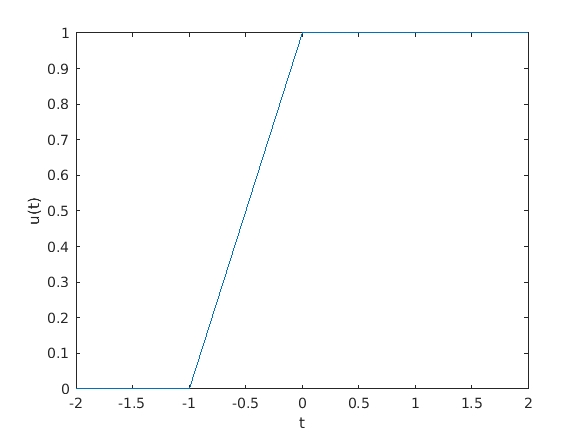

t= (-2:2);
plot (t,u(t));
xlabel ('t');ylabel ('u(t)');

Vemos que 2 cosas que no queremos pasan, al escalar la gráfica hasta el borde la mayoría se pierde, además MatLab conecta los datos de la gráfica con líneas, provocando que sea difícil crear de verdad una discontinuidad, como para el vector que definimos la discontinuidad es grande, se hace una línea inclinada entre -1 y 0, cosa que no se busca que ocurra y que además dificulta la apreciación de que hay un brinco.

El primer problema se resuelve al hacer más grande el área de trabajo con el comando axis, y el segundo se minimiza al agregar más puntos al vector t:

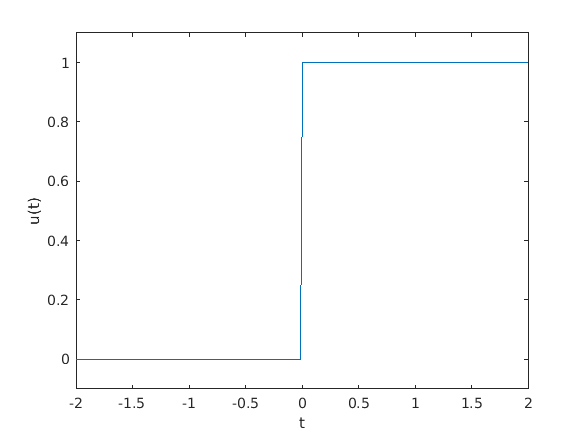

t= (-2:0.01:2);
plot (t,u(t));
xlabel ('t');ylabel ('u(t)');
axis ([-2 2 -0.1 1.1]);

Como se observa, la gráfica mostrada es una representación mejorada, aunque no perfecta de la función u(t).

Se pueden mezclar los operadores relacionales con los operadores lógicos para crear expresiones diferentes. Por ejemplo, (t>0)&(t<1) y -((t<=0) | (t>=1)) ambas expresiones evalúan si 0<t<1. para demostrar lo anerior definimos y graficamos el impulso unitario p(t)=u(t)-u(t-1), como sigue:

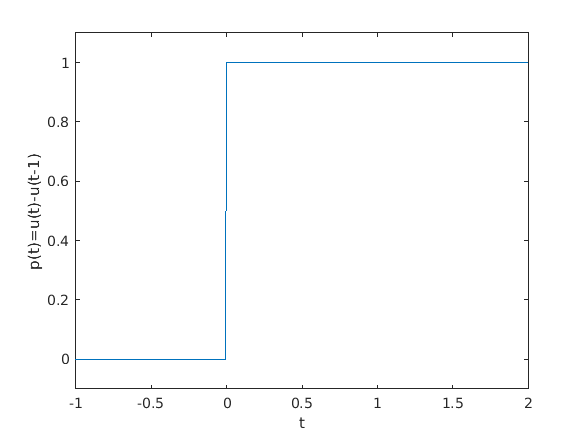

p= @(t) (t>=0 | t>=1);
t= (-1:0.01:2);
plot (t,p(t));
xlabel ('t');ylabel ('p(t)=u(t)-u(t-1)');
axis ([-1 2 -0.1 1.1]);

### M1.3 Visualizar operaciones de la variable independiente

Considerando g(t)=f(t)u(t)=$e^{-t} \left(2\pi t\right)u\left(t\right)$ una versión posible de f(t). MatLab no puede multiplicar funciones anónimas, es decir que reporta un error para g=f*u, si f y u son funciones anónimas. En lugar de hacer el producto así, g(t) se debe definir explicitamente:

g= @(t) exp(-t).*cos(2*pi*t).*(t>=0)

g = function_handle with value:
    @(t)exp(-t).*cos(2*pi*t).*(t>=0)


Y su gráfica quedaría como:

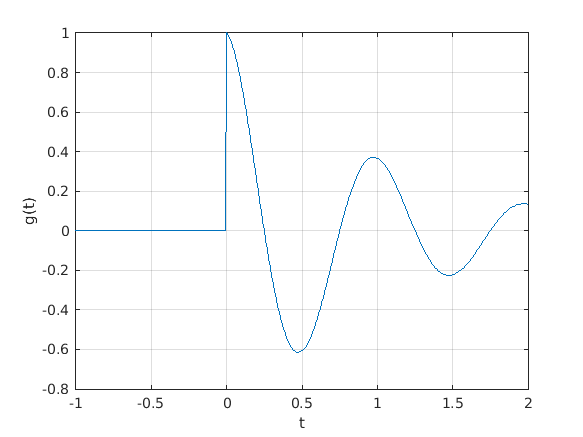

plot (t,g(t));xlabel ('t');ylabel ('g(t)');grid;

Una operación combinada de escalamiento y traslación se representa por g(at+b), donde a y b son constantes reales aleatorias. Como ejemplo, se grafica g(2t+1) para el intervalo (-2$\le$t$\le$2) con a=2, la función se comprime por un factor de 2, resultando en el doble de oscilaciones por cada unidad de t. Y como b>0, la gráfica se traslada a la izquierda. La gráfica es entonces considerando la función que definimos anteriormente g(t) como:

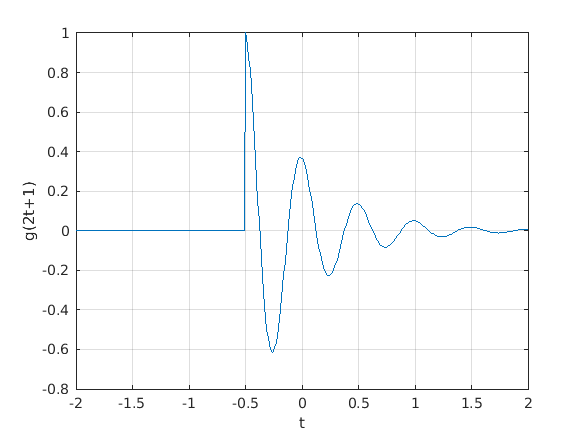

t= (-2:0.01:2);
plot (t,g(2*t+1));xlabel ('t');ylabel ('g(2t+1)');grid;

Comparando ambas gráficas la de g(t) y la de g(2t+1) vemos que efectivamente se realizó el escalamiento y traslación esperados:

Si ahora graficamos g(-t+1) en el mismo intervalo (-2$\le$t$\le$2). Como a<0, la gráfica se verá reflejada. Y como b>0, la gráfica final se traslada a la derecha. Obtenemos entonces la gráfica:

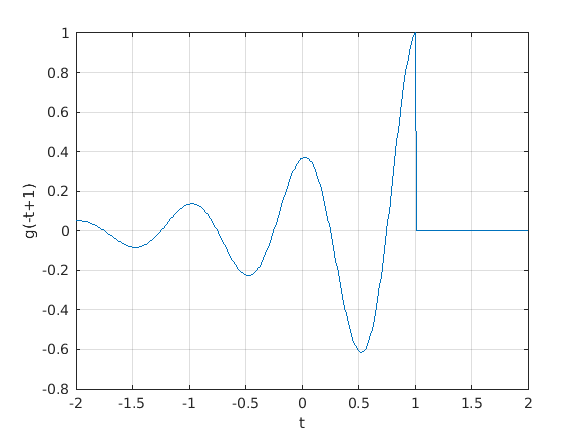

plot (t,g(-t+1));xlabel ('t');ylabel ('g(-t+1)');grid;

Como observamos, la gráfica confirma que se reflejó la señal y se trasladó a la derecha.

Si ahora graficamos una función más complicada como: h(t)=g(2t+1)+g(-t+1) para el intervalo (-2$\le$t$\le$2). Vemos como MatLab hace fácil la gráfica, que a mano podría complicarse bastante.

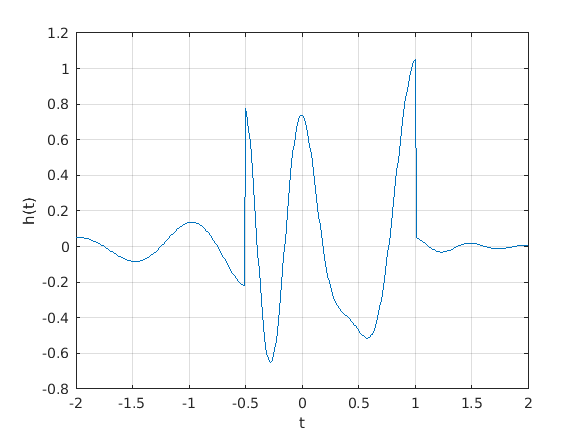

plot (t,g(2*t+1)+g(-t+1));xlabel ('t');ylabel ('h(t)');grid;

### M.1.4 Integración numérica y estimación de la energía de una señal

Considerando la señal $x\left(t\right)=e^{-t} \left(u\left(t\right)-u\left(t-1\right)\right)$. La energía de x(t) se expresa como: $E_x =\int_{-\infty }^{\infty } {\left|x\left(t\right)\right|}^2 \textrm{dt}=\int_0^1 e^{-2t} \textrm{dt}$, y al integrar, se produce: $E_x =0\ldotp 5\left(1-e^{-2} \right)\approx 0\ldotp 4323$. La integral de energía puede evaluarse también numericamnete. Primero creamos la función x(t).

x= @(t) exp(-t).*((t>=0)&(t<1))

x = function_handle with value:
    @(t)exp(-t).*((t>=0)&(t<1))


Si hacemos que $\Delta t=0\ldotp 01$, un vector apropiado de t se crea.

t= (0:0.01:1);

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


El resultado final se calcula utilizando el comando sum, que hace una suma de Riemman o de rectángulos sobre toda el área que comprende la función:

E_x= sum(x(t).*x(t)*0.01)

E_x = 0.4367

El resultado no es exacto, pero tiene 1% de error relativo, por lo que se aproxima mucho. Si reducimos $\Delta t$, la aproximación mejora. Si por ejemplo hacemos $\Delta t=0\ldotp 001$

t= (0:0.001:1);
E_x= sum(x(t).*x(t)*0.001)

E_x = 0.4328

El error disminuye hasta 0.1% de error relativo, lo que es despreciable en la mayor parte de los casos.

Pero, la aproximación rectangular aunque se visualiza fácil, no es el mejor método de integración numérica. La función quad de MatLab implementa una mejor tpecnica de integración, llamada regla de cuadratura de Simpson adaptativa recursiva. Para funcionar quad, requiere una función describiendo el integrando, el límite de integración inferior y el superior. No se necesita especificar $\Delta t$.

Para usar quad, primero hay que describir el integrando:

x_squared= @(t) exp(-2*t).*((t>=0)&(t>1))

x_squared = function_handle with value:
    @(t)exp(-2*t).*((t>=0)&(t>1))


Calculando $E_x$, resulta:

E_x= quad(x_squared,0,1)

E_x = 0

En este caso el error relativo es -0.0026%.

Las mismas técnicas se pueden aplicar para estimar la energía de señales más complejas.Considera g(t) que definimos antes. Su energía se expresa como: $E_g =\int_0^{\infty } e^{-2t} \cos^2 \left(2\pi t\right)\textrm{dt}$. Una solución de forma cerrada existe, pero se puede complicar. MatLab resuelve el problema más rápidamente.

g_squared= @(t) exp(-2*t).*(cos(2*pi*t).^2).*(t>=0);

Aunque el límite de integración superior es infinito, la curva exponencial asegura que g(t) es 0 mucho antes de t=100. Así usamos como límite superior t=100 junto con un $\Delta t=0\ldotp 001$.

t= (0:0.001:100);
E_g= sum(g_squared(t)*0.001)

E_g = 0.2567

Una aproximación un poco mejor se obtiene al usar la función quad:

E_g= quad(g_squared,0,100)

E_g = 0.2562

Por último como ejercicio comprobaremos usando sum y quad, que la señal h(t) definida previamente, es $E_h =0\ldotp 3768$:

h_squared= @(t) (exp(-(2*t+1)).*(cos(2*pi*(2*t+1))).*((2*t+1)>=0)+exp(-(-t+1)).*(cos(2*pi*(-t+1))).*((-t+1)>=0)).^2;
t=(-2:0.001:2);
E_h= sum(h_squared(t)*0.001)

E_h = 0.3769

Y el resultado utilizando quad es:

E_h= quad(h_squared,-3,3)

E_h = 0.3767

Ambos se aproximan mucho al valor de la energía $E_h =0\ldotp 3768$ comprobando que MatLab simplifica mucho el trabajo para cálculos así de complejos y brinda resultados muy aproximados.

## Problema 2

### 1.1.2. Para la señal x(t) mostrada en la gráfica 1, grafica:

- x (t - 4)

- x (t/1.5)

- x (- t)

- x (2t - 4)

- x (2 - t)

La señal original x(t) es:

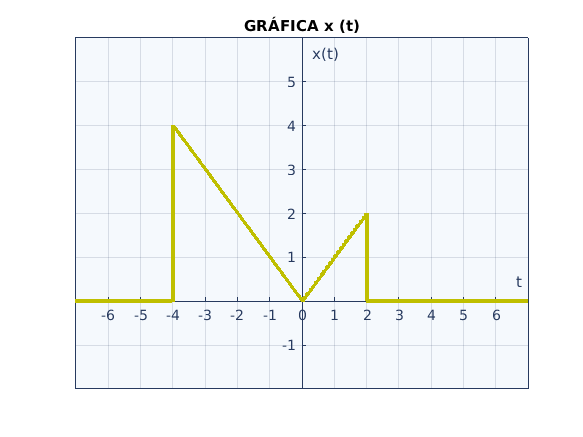

x= @(t) (-t).*((t<=0)&(t>=-4))+t.*((t>=0)&(t<=2));
t=-12:0.01:12;
Grafipro1(t,x(t));
title('GRÁFICA x (t)');

**a)** Haciendo una traslación horizontal 4 unidades a la derecha de la señal original obtenemos:

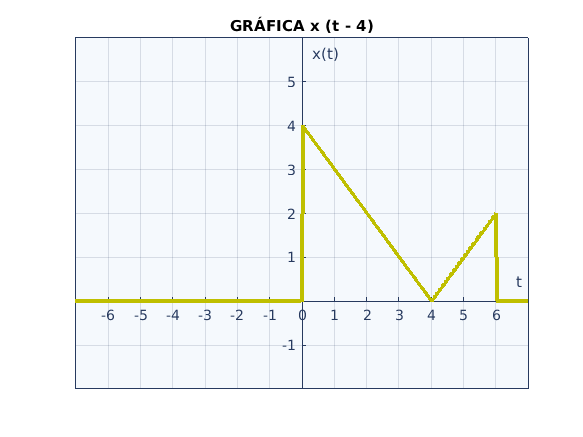

Grafipro1(t,x(t-4));
title('GRÁFICA x (t - 4)');

**b)** Ahora haciendo un escalamiento de t/1.5 que desarrollado es 2t, tenemos una compresión en factor 2 de la función original.

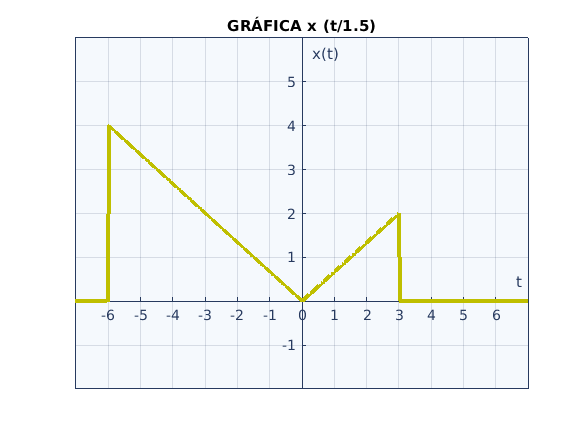

Grafipro1(t,x(t/1.5));
title('GRÁFICA x (t/1.5)');

**c)** Invertimos en el tiempo a la función x(t) y obtenemos la gráfica:

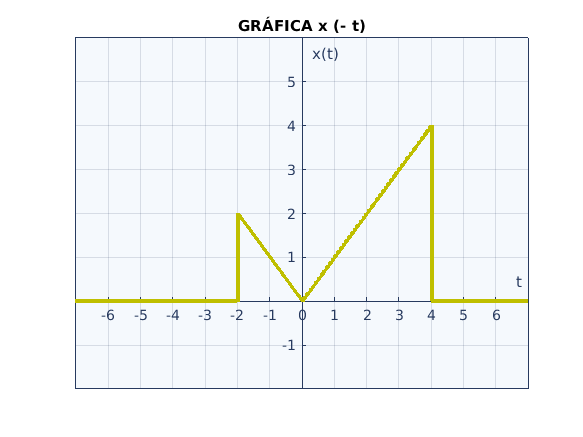

Grafipro1(t,x(-t));
title('GRÁFICA x (- t)');

**d)** Ahora tenemos una operación combinada, primero una traslación de 4 unidades a la derecha y además un escalamiento que produce una compresión en un factor de 2, si observamos es la combinación de los incisos a) y b) y tenemos entonces la gráfica:

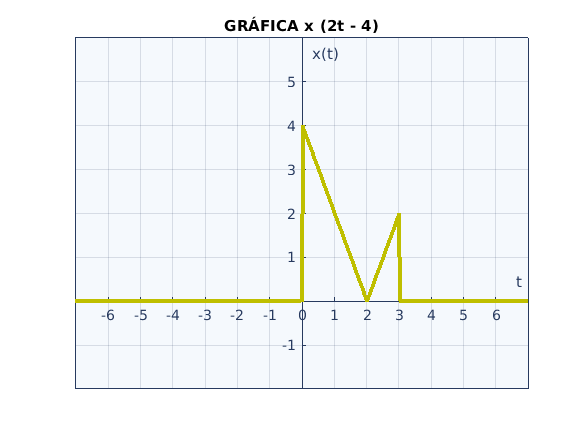

Grafipro1(t,x(2*t-4));
title('GRÁFICA x (2t - 4)');

**e)** Por último tenemos una traslación de 2 unidades a la izquierda seguida por la inversión de la función en el tiempo, lo que nos da como resultado:

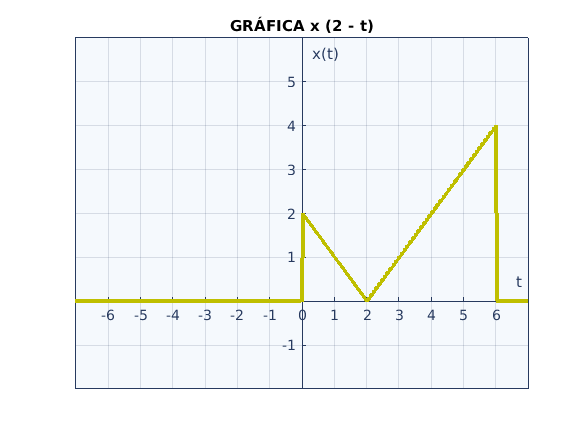

Grafipro1(t,x(2-t));
title('GRÁFICA x (2 - t)');

## Problema 3

### Función 1 $f(t)=e^{-at}u(t);\ F(\omega)=\frac{1}{j\omega+a}$:

Para graficar llamamos a la función graficarenr y le pasamos el dominio (intervalo para el que se quiere graficar) y la función a graficar como una cadena de caracteres y con t como variable independiente.

NOTA:Para las siguientes pruebas se toma a=1/2y n=2.

Como primera gráfica obtenemos:

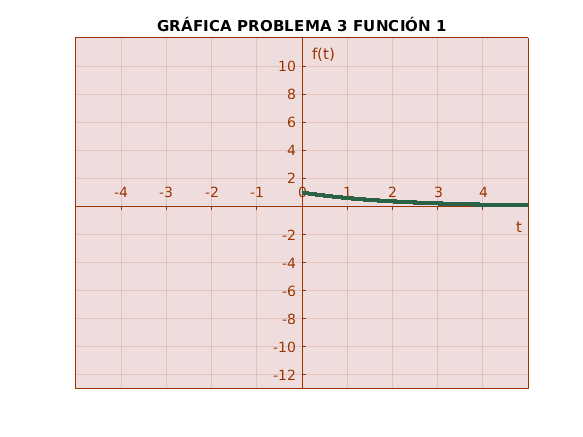

funcion1= 'exp(1/2*-t).*(t>=0)';
dominio= (0:0.01:5);
graficarenr (dominio,funcion1);
title('GRÁFICA PROBLEMA 3 FUNCIÓN 1');

La gráfica de su fase y magnitud son respectivamente utilizando dos funciones, graficarfase y graficarmag,ambas reciben el intervalo para el que va a calcular la función y la función, solo que una grafíca la parte real y la otra la imaginaria de la función dada:

Grafica la parte imaginaria (graficarfase).

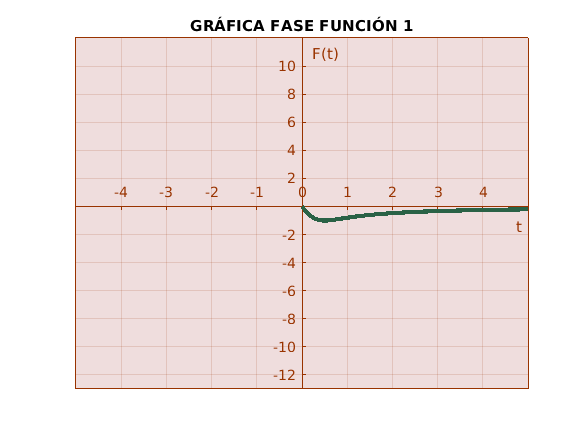

funcion1= '1./(j*w+1/2)';
graficarfase (dominio,funcion1);
ylabel('F(t)');
title('GRÁFICA FASE FUNCIÓN 1');

Grafica la parte real (graficarmag).

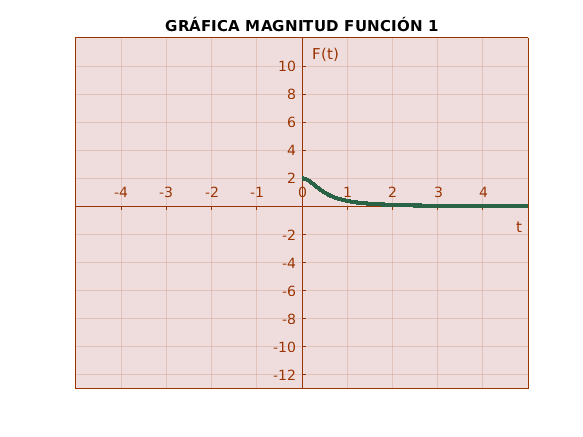

graficarmag (dominio,funcion1);
ylabel('F(t)');
title('GRÁFICA MAGNITUD FUNCIÓN 1');

Analogamente para la función 2 y 3 tenemos:

### Función 2 ${f\left(t\right)=\textrm{te}}^{-\alpha t} u\left(t\right);F\left(t\right)=\frac{1}{{\left(j\omega +\alpha \right)}^2 }$:

Función f(t):

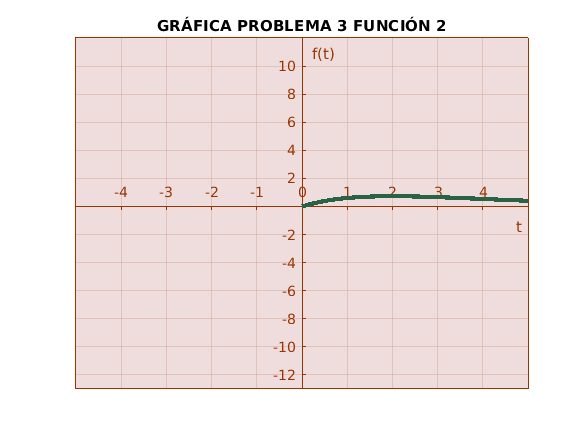

funcion2= 't.*exp(1/2*-t).*(t>=0)';
dominio= (0:0.01:5);
graficarenr (dominio,funcion2);
title('GRÁFICA PROBLEMA 3 FUNCIÓN 2');

Grafica la parte imaginaria (graficarfase).

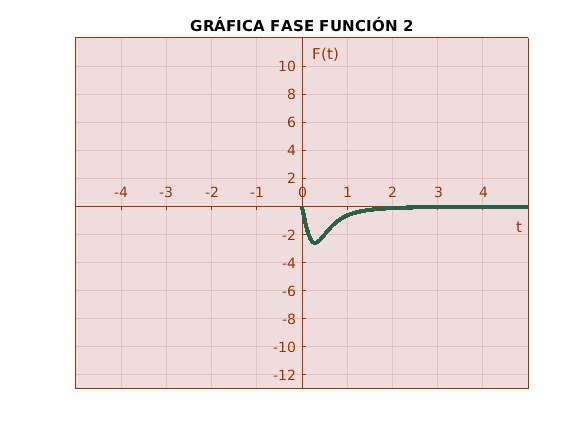

funcion2= '1./(j*w+1/2).^2';
graficarfase (dominio,funcion2);
ylabel('F(t)');
title('GRÁFICA FASE FUNCIÓN 2');

Grafica la parte real (graficarmag).

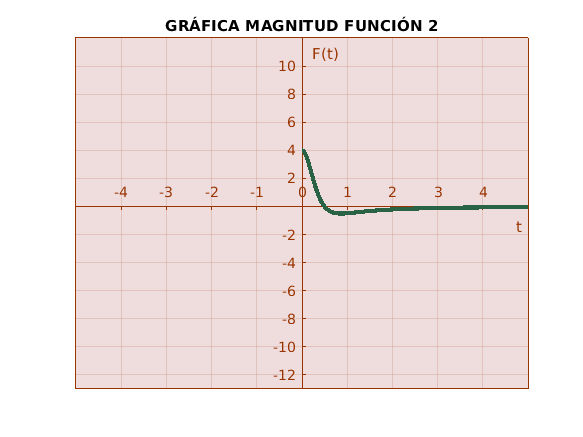

graficarmag (dominio,funcion2);
ylabel('F(t)');
title('GRÁFICA MAGNITUD FUNCIÓN 2');

### Función 3 ${f\left(t\right)=t^n e}^{-\alpha t} u\left(t\right);F\left(t\right)=\frac{n!}{{\left(j\omega +\alpha \right)}^{n+1} }$:

Función f(t):

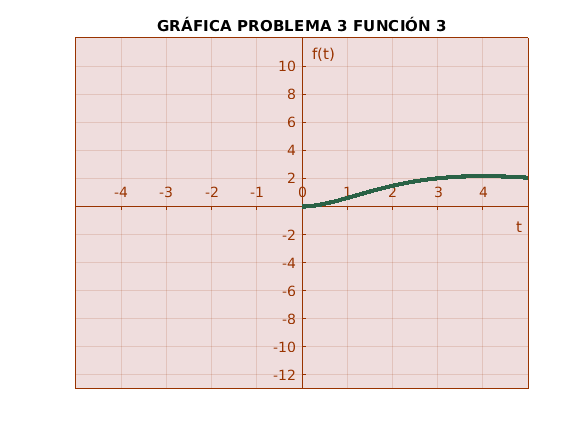

funcion3= '(t.^2).*exp(1/2*-t).*(t>=0)';
dominio= (0:0.01:5);
graficarenr (dominio,funcion3);
title('GRÁFICA PROBLEMA 3 FUNCIÓN 3');

Grafica la parte imaginaria (graficarfase).

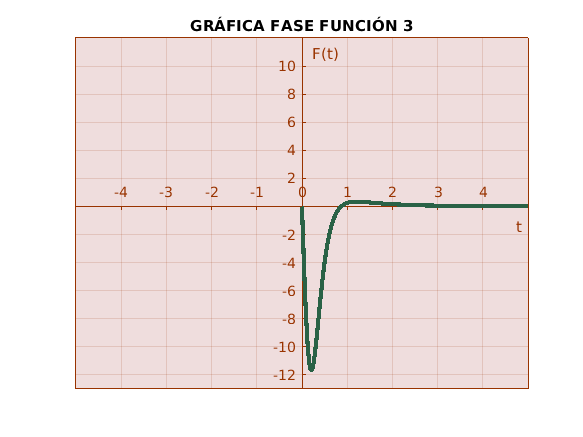

funcion3= 'factorial(2)./(j*w+1/2).^(2+1)';
graficarfase (dominio,funcion3);
ylabel('F(t)');
title('GRÁFICA FASE FUNCIÓN 3');

Grafica la parte real (graficarmag).

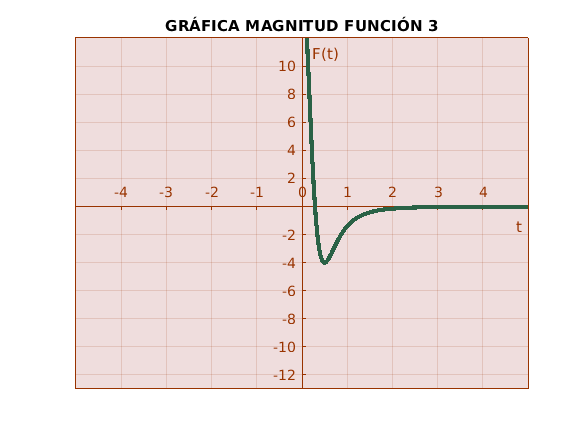

graficarmag (dominio,funcion3);
ylabel('F(t)');
title('GRÁFICA MAGNITUD FUNCIÓN 3');

## Problema 4

Realizamos la gráfica de las tres funciones que vimos en el problema 3 pero ahora en $R^2$:

### Función 1 ${f\left(t\right)=e}^{-\alpha t} u\left(t\right);F\left(t\right)=\frac{1}{j\omega +\alpha }$:

Una funcion llamada graficarenr2 recibe el intervalo y la función a graficar y utilizando comandos de MatLab grafica en 3 ejes sus partes real e imaginaria para el intervalo dado.

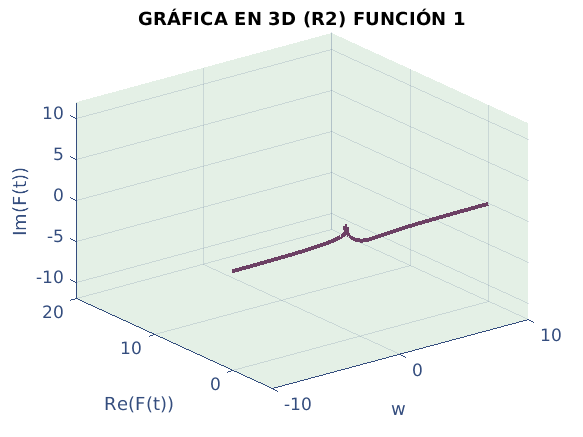

w=-10:0.001:10;
F= @(w) 1./((w*j)+(0.5));
graficarenr2 (w,funcion1);
title('GRÁFICA EN 3D (R2) FUNCIÓN 1');

### Función 2 ${f\left(t\right)=\textrm{te}}^{-\alpha t} u\left(t\right);F\left(t\right)=\frac{1}{{\left(j\omega +\alpha \right)}^2 }$:

Se vuelve a usar la fución graficarenr2 para la expresión 2:

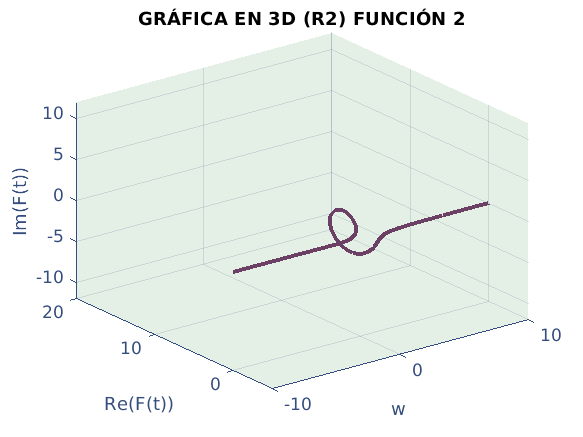

w=-10:0.001:10;
graficarenr2 (w,funcion2);
title('GRÁFICA EN 3D (R2) FUNCIÓN 2');

### Función 3 ${f\left(t\right)=t^n e}^{-\alpha t} u\left(t\right);F\left(t\right)=\frac{n!}{{\left(j\omega +\alpha \right)}^{n+1} }$:

Por último con graficarenr2 generamos la expresión 3:

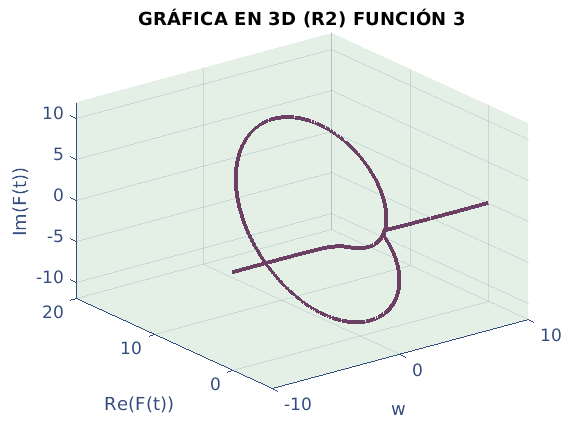

w=-10:0.001:10;
graficarenr2 (w,funcion3);
title('GRÁFICA EN 3D (R2) FUNCIÓN 3');

## Problema 5

Se realizó la app indicada en las instrucciones, el archivo se adjunta a la entrega para revisión; y la captura del funcionamiento queda como: